# **Vision Artificial. GIEC.**

# **	Sistemas de Vision Artificial. GIC.**

**	Miguel Angel Garcia, Juan Manuel Miguel, Sira Palazuelos. **

**  Departamento de Electrónica. Universidad de Alcalá.**

**Nombre:**

**Fecha:**

# Tema 4. Ejercicio 2 - Identificación de objetos circulares

1) Lee la imagen

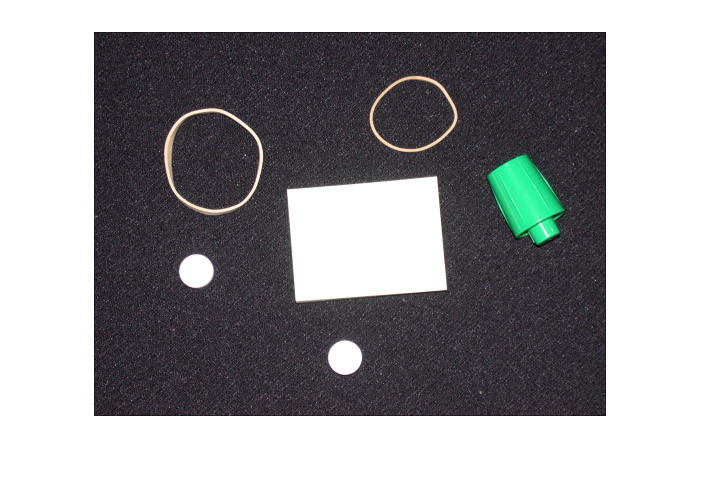

RGB = imread('pillsetc.png');
imshow(RGB);

2) Umbraliza la imagen

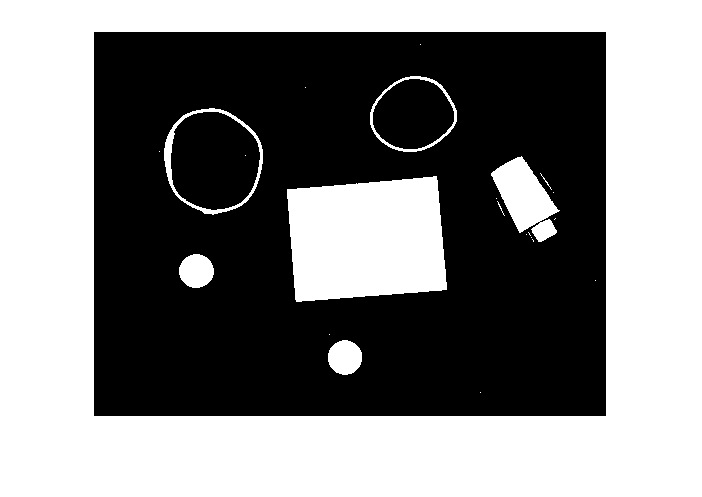

I = rgb2gray(RGB);
bw = imbinarize(I);
imshow(bw)

3) Elimina el ruido

Usando operaciones morfológicas se eliminan los píxeles que no pertenecen a los objetos de interés.

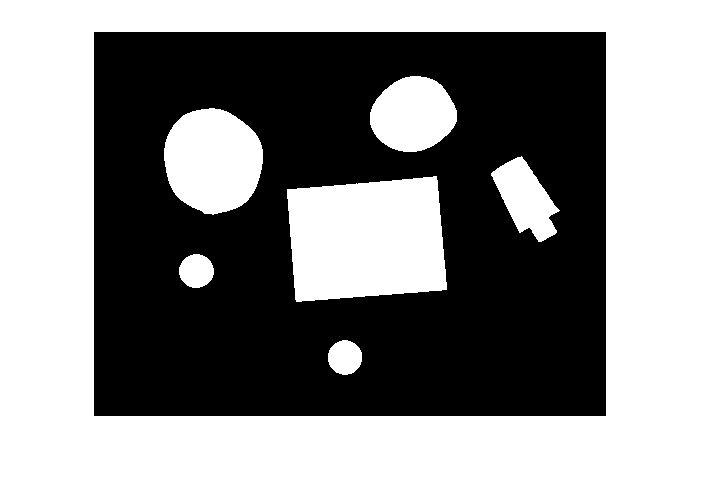

% remove all object containing fewer than 30 pixels
bw = bwareaopen(bw,30);

% fill a gap in the pen's cap
se = strel('disk',2);
bw = imclose(bw,se);

% fill any holes, so that regionprops can be used to estimate
% the area enclosed by each of the boundaries
bw = imfill(bw,'holes');

imshow(bw)

4) Encuentra los contornos

Nos centramos sólo en los límites exteriores. La opción `'noholes' `acelerará el proceso al evitar que la función `bwboundaries` busque contornos internos. 

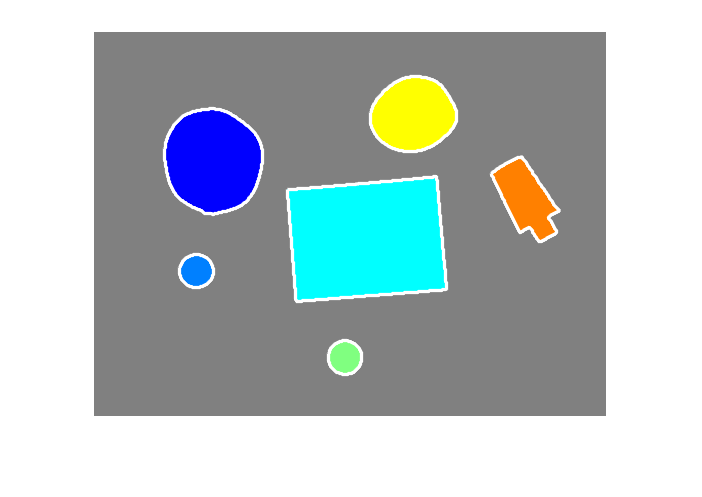

[B,L,n,A] = bwboundaries(bw,'noholes'); % Returns B, a cell array of boundary pixel locations, and matrix L where objects and holes are labeled..

% Display the label matrix 
imshow(label2rgb(L, @jet, [.5 .5 .5]))

hold on  % to draw the next in the same figure

% draws the boundaries of each object.
for k = 1:n
  boundary = B{k};
  plot(boundary(:,2), boundary(:,1), 'w', 'LineWidth', 2)
end

Se pide:

- Utilice la ayuda de Matlab para conseguir información sobre la función `regionprops `(parámetros requeridos, propiedades que calcula, etc.)`.`

- Usando dicha función, calcule el área, el perímetro y la circularidad de cada objeto de la imagen previa. 

- Umbralizando el valor de la circularidad, resalte los objetos que sean aproximadamente circulares (p.ej., pintando las boundaries de color diferente). Puede utilizar un slidebar para verificar la influencia del valor del umbral en el conjunto de objetos resaltados.

- Cargue la imagen` 'google.jpg'``,` rellene los agujeros internos de las letras con la función imfill(bw,'holes') y determine, calculando a partir de parámetros obtenidos con la función `regionprops`, si los objetos son cóncavos o convexos. Resalte con diferente color los objetos cóncavos y los convexos, utilizando el borde del objeto convexo ('ConvexHull'). Nota: En esta pregunta hay que tener en cuenta que el primer plano es oscuro y el fondo claro, por lo que hay que modificar los pasos 2 y 3 para obtener un etiquetado correcto. 